clc
close all
clear all

T_Filename = input('behavior data file (format: ''filename.xlsx'') : ');
N_Filename = input('cell trace data file (format: ''filename.xlsx'') : ');
time_shift = 0;

% Create raw data matrix
tagged_data = xlsread(T_Filename);
neuron_data = xlsread(N_Filename);
[~, ~, raw] = xlsread(T_Filename);

% Correct the time shift
tagged_data = tagged_data-time_shift;

% Create positive and negative neuron data for positive and negative
% correlation
Positive_neuron_data = neuron_data;
Positive_neuron_data(Positive_neuron_data <= 0) = 0;
Negative_neuron_data = neuron_data;
Negative_neuron_data(Negative_neuron_data >= 0) = 0;

% Store the sizes of the data
tagged_data_size = size(tagged_data);
neuron_data_size = size(neuron_data);
    

% print behavior option menu
behavior_size = tagged_data_size(2)/2;
fprintf('\nBEHAVIOR OPTIONS: \n');


BEHAVIOR OPTIONS: 


for behavior_it = 1:behavior_size
    fprintf(int2str(behavior_it) + ". " + convertCharsToStrings(raw(1, 2*behavior_it-1)) + '\n');
end

1. 28


% receive input for which behavior to analyze
behavior = input('\nbehavior to analyze (format: #) : ');
behavior_fullname = raw(1, 2*behavior-1);
behavior_name=string(behavior_fullname);
fprintf("\nSelected Behavior: " + behavior_fullname + '\n');


Selected Behavior: 28



r = 2*behavior-1;

% Creating empty array of the same size as the Behavior data
behavior_data  = zeros(neuron_data_size(1), neuron_data_size(2));

% Create an array complete time data increments from neuron data
Time = neuron_data(:, 1);
Time = Time - Time(1);

% Initialize arrays that store the data point numbers for Rearing or MB
% start and stop
behavior_data_size = find(tagged_data(:, r) > 0, 1, 'last');

if isempty(behavior_data_size) 
    behavior_data_size = 0; end

Behavior_start_stop = zeros(tagged_data_size(1), 2);

% Initialize an array, the same size as the neuron data, that stores
% increasing integer values for each behavior window
epochs = zeros(neuron_data_size(1), 1);
Behaviori = 1;

for iterator1 = 1:tagged_data_size(1)
    Behavior_start = find(Time >= tagged_data(iterator1, r), 1, 'first');
    Behavior_stop = find(Time >= tagged_data(iterator1, r+1), 1, 'first');
    
     % Records the stop and start data points
    if (iterator1 <= behavior_data_size && ~isempty(Behavior_start) && ~isempty(Behavior_stop) && Behavior_start~=1 && Behavior_stop ~=1)
        Behavior_start_stop(Behaviori, 1) = Behavior_start;
        Behavior_start_stop(Behaviori, 2) = Behavior_stop;
        Behaviori = Behaviori+1;
    end
    
    % Fills the cells with 1s in the given time interval
    behavior_data(Behavior_start:Behavior_stop, 1:neuron_data_size(2)) = 1; 
    
    % Fills the 'epochs' array with the intended values
    epochs(Behavior_start:Behavior_stop, 1) = iterator1;
    
end

behavior_data_size = find(Behavior_start_stop(:,1) > 0, 1, 'last');

if isempty(behavior_data_size)
    behavior_data_size = 0; 
end

Behavior_start_stop(behavior_data_size+1:end,:) = [];

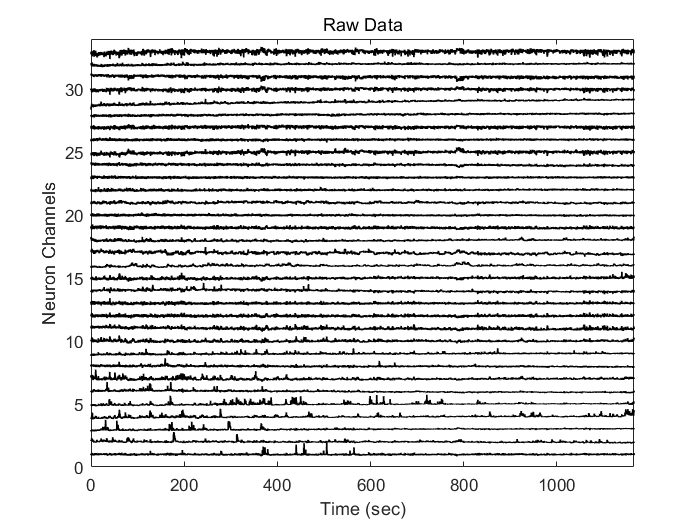

% Plot all neuronal activity
% Plot all the neuron data channels on the same graph, normalized and separated
figure (1)
Normalizer = max(max(neuron_data(:,2:end)));
plot((Time - Time(1)), neuron_data(:, 2)/Normalizer + 1, 'Color', 'k', 'LineWidth', 1)
hold on
for channels = 3:neuron_data_size(2)
    plot((Time - Time(1)), neuron_data(:, channels)/Normalizer + channels - 1, 'Color', 'k', 'LineWidth', 1)
end

% Set axis size based on size of data
axis([0 (Time(end) - Time(1)) 0 neuron_data_size(2)])

% % Fill in the areas on the graph (Green --> MB, Red --> Rearing)
% area((Time - Time(1)), MB_data(:, 1)*neuron_data_size(2),'FaceColor','g', 'FaceAlpha',.2,'EdgeAlpha', 0.001)
% area((Time - Time(1)), Rearing_data(:, 1)*neuron_data_size(2),'FaceColor','r', 'FaceAlpha',.2,'EdgeAlpha', 0.001)
title('Raw Data') 
xlabel('Time (sec)')
ylabel('Neuron Channels')

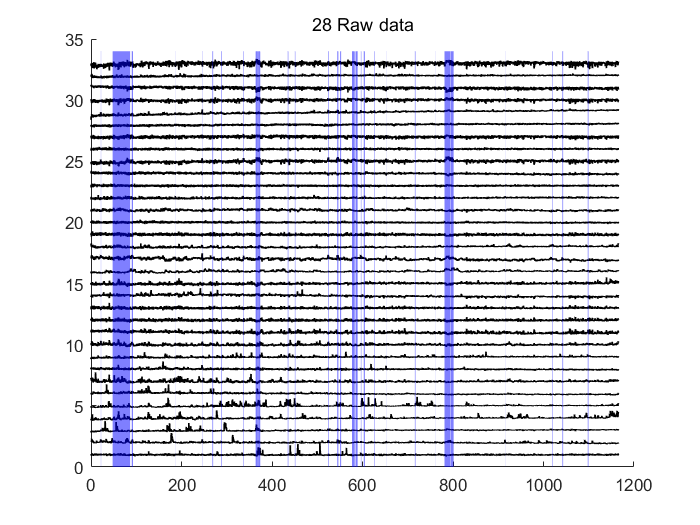



% Plot behavior time area on neuronal activity
f1 = gca; % Get rescent figure properties(figure(1))

f1Behavior = figure(101);
ax1Behavior = axes;
copyobj(findobj(f1,'visible','on','type','line'), ax1Behavior);
behavior_title = sprintf('%s Raw data', behavior_name);
title(behavior_title)
% title(behavior_fullname + "(Raw Data)")
hold on;

for i = 1:size(Behavior_start_stop,1)
    t1 = Time(Behavior_start_stop(i,1));
    
    t2 = Time(Behavior_start_stop(i,2));
    area([t1 t2], [neuron_data_size(2)  neuron_data_size(2)],...
        'EdgeColor','none','FaceColor','b', 'FaceAlpha',0.5);
end
hold off;

% % Showing all the Behavoir points in one Graph
% f100 = gca % Get recent figure properties
% 
% f

%% Filter - Online deconvolution
% Filter the neuron data using Fast Online Deconvolution of Calcium Imaging Data

% User need to install or setup to run this code
% Friedrich-deconvolveCa: https://github.com/zhoupc/OASIS_matlab
% go to sub directory called OASIS and run ">> setup" if it shows "Error in
% deconvolveCa (line 70) options.sn = GetSn(y);"

filtered_data = zeros(neuron_data_size(1), 2*(neuron_data_size(2) - 1));
for iterator2 = 1:(neuron_data_size(2) - 1)
   [filtered_data(:, iterator2*2 - 1), filtered_data(:, iterator2*2)] = ...
       deconvolveCa(neuron_data(:, iterator2 + 1), 'ar1', 'foopsi', 'optimize_pars');
end

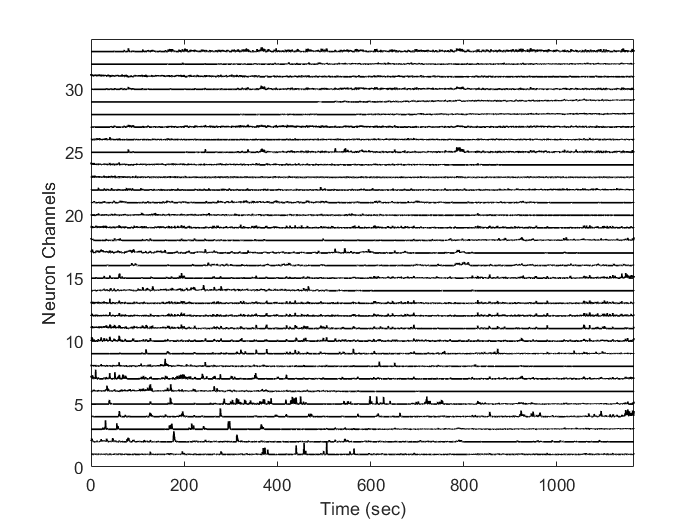


%Plot the filtered data just like the original data
figure (2)
Normalizer = max(max(filtered_data(:, 1:2:end)));
plot((Time - Time(1)), filtered_data(:, 1)/Normalizer + 1, 'Color', 'k', 'LineWidth', 1)
hold on
for iterator3 = 2:(neuron_data_size(2) - 1)
   corrected_filtered_data = filtered_data(:, iterator3*2 - 1)/Normalizer + iterator3;
   plot((Time - Time(1)),corrected_filtered_data,'Color', 'k', 'LineWidth', 1) 
end

% Set axis size based on size of data
axis([0 (Time(end) - Time(1)) 0 neuron_data_size(2)])

xlabel('Time (sec)')
ylabel('Neuron Channels')

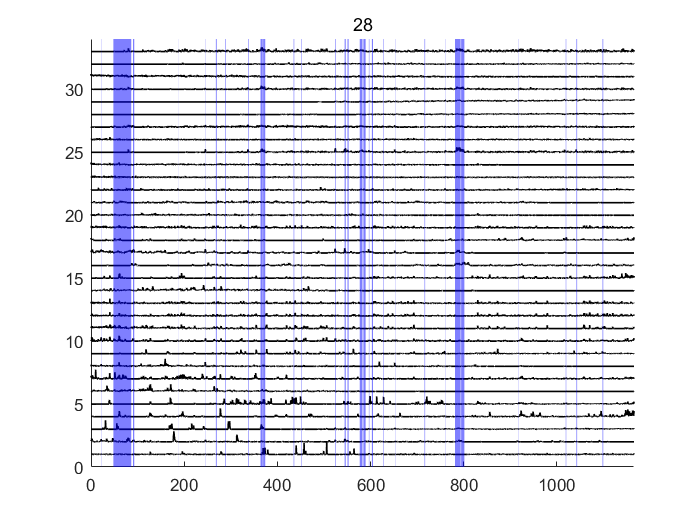


% Plot behavior time area on neuronal activity
f2 = gca; % Get rescent figure properties(figure(1))

f2Behavior = figure(201);
ax2Behavior = axes;
copyobj(findobj(f2,'visible','on','type','line'), ax2Behavior);
title(behavior_fullname)
hold on;
for i = 1:size(Behavior_start_stop,1)
    t1 = Time(Behavior_start_stop(i,1));
    t2 = Time(Behavior_start_stop(i,2));
    area([t1 t2], [neuron_data_size(2)  neuron_data_size(2)],...
        'EdgeColor','none','FaceColor','b', 'FaceAlpha',0.5);
end

axis([0 (Time(end) - Time(1)) 0 neuron_data_size(2)])
hold off;

%% ROC
% Compute and plot the ROC curves for the orignal and filtered data

% USER INPUT
N_cell_number = input('Cell number : '); % iput cell number here to plot ROC curve (cell number ends at neuron_data_size(2) "34"
filter = input('0-original data, 1-filtered data : '); % 0: no filter, 1: filter
shuffle_size = input('shuffle size : ');
hist_bin_num = input('histogram bin number : ');

%  INITIALIZATION
if filter == 0
    wanted_neuron_data = neuron_data;
else
    wanted_neuron_data = filtered_data;
end

% Create arrays to store the auROC data
auROC_neuron_data = zeros(1, neuron_data_size(2) - 1);
auROC_raw_data = zeros(1, neuron_data_size(2) - 1);
auROC_filtered_data = zeros(1, neuron_data_size(2) - 1);

% neuron_data_size(2) looping for cells
for iterator4 = 2:neuron_data_size(2)
    [~, ~, ~, auROC_raw_data(1, iterator4 - 1)]...
        = perfcurve(behavior_data(:, 1), neuron_data(:, iterator4), 1);
    
    [~, ~, ~, auROC_filtered_data(1, iterator4 - 1)]...
        = perfcurve(behavior_data(:, 1), filtered_data(:, (iterator4 - 1)*2 - 1), 1);
end
if filter == 0
    auROC_neuron_data = auROC_raw_data;
else
    auROC_neuron_data = auROC_filtered_data;
end

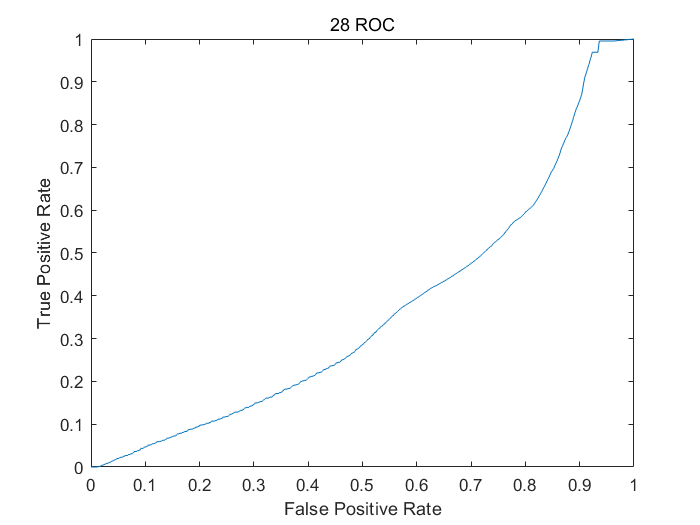

% ROC plot
figure(999)
if filter == 0
    [x, y, ~, auROC_neuron_data(1, N_cell_number - 1)]...
        = perfcurve(behavior_data(:, 1), neuron_data(:, N_cell_number), 1);
     plot(x,y)
else
    [x, y, ~, auROC_neuron_data(1, N_cell_number - 1)]...
        = perfcurve(behavior_data(:, 1), filtered_data(:, (N_cell_number - 1)*2 - 1), 1);
     plot(x,y)
end
name = sprintf('%s ROC', behavior_name);
title(name)
xlabel('False Positive Rate')
ylabel('True Positive Rate')

% Calculate correlation factors
behavior_data_correlation_factors_raw = (auROC_raw_data - 0.5)*2;
behavior_data_correlation_factors_filtered = (auROC_filtered_data - 0.5)*2;
behavior_data_correlation_factors = (auROC_neuron_data - 0.5)*2;


% Store actual RS value of a specific cell
RS_actual = behavior_data_correlation_factors(1, N_cell_number);

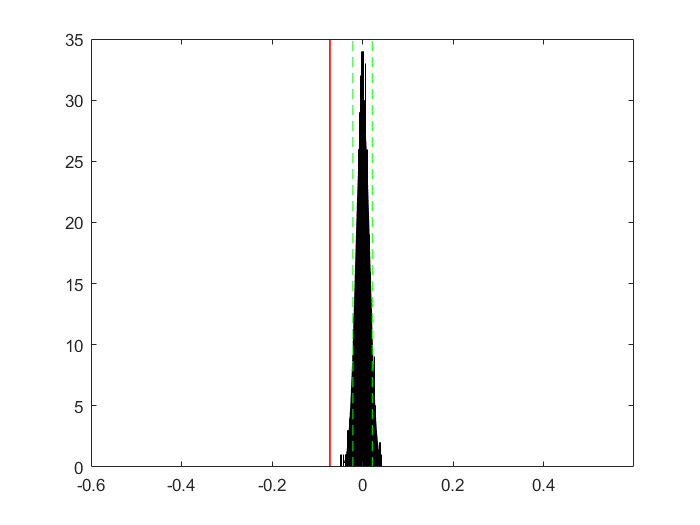

% Shuffled ROC histogram calc/plot

shuffled_auROC_neuron_data = zeros(shuffle_size, neuron_data_size(2) - 1);

original = zeros(neuron_data_size(2),1);
shuffled = zeros(neuron_data_size(2),1);

for shuffle_it = 2:neuron_data_size(2)
    for random_it = 1:shuffle_size
        original = wanted_neuron_data(:,shuffle_it);
        shuffled = original(randperm(size(original,1)),:);
        
        [~, ~, ~, shuffled_auROC_neuron_data(random_it, shuffle_it - 1)]...
            = perfcurve(behavior_data(:, 1), shuffled, 1);
    end
end

% convert auROC --> RS
shuffled_RS_neuron_data = (shuffled_auROC_neuron_data - 0.5) * 2;

sorted = sort(shuffled_RS_neuron_data);  % sort RS data in ascending order

lowerlimit = sorted(round(shuffle_size*0.05), N_cell_number);
upperlimit = sorted(round(shuffle_size*0.95), N_cell_number);

% histogram
bellcurve = histfit(shuffled_RS_neuron_data(:,N_cell_number), hist_bin_num);
set(bellcurve(2),'color','k');
xlim([-0.6 0.6]);
ylim = get(gca,'YLim');
line([lowerlimit, lowerlimit], [0, ylim(2)], 'LineStyle', '--', 'Color', 'g')
line([upperlimit, upperlimit], [0, ylim(2)], 'LineStyle', '--', 'Color', 'g')
line([RS_actual, RS_actual], [0, ylim(2)], 'Color', 'r', 'LineWidth', 1)

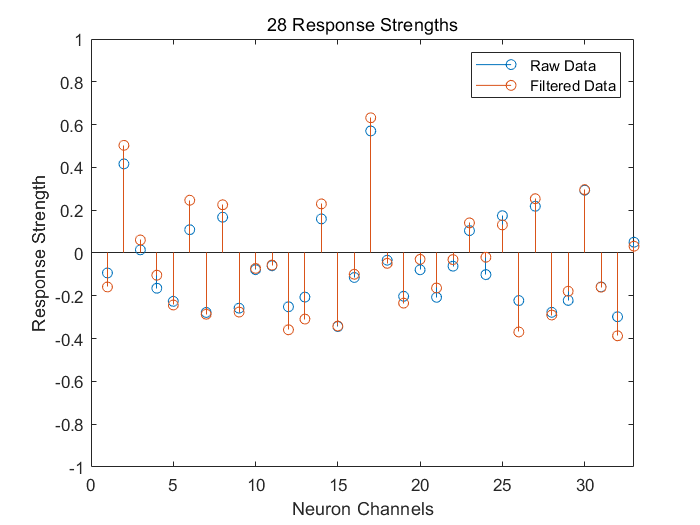

% stem graph
figure(3)
stem(behavior_data_correlation_factors_raw)
hold on
stem(behavior_data_correlation_factors_filtered)

name = sprintf('%s Response Strengths', behavior_name);
title(name)
xlabel('Neuron Channels')
ylabel('Response Strength')
legend('Raw Data', 'Filtered Data')
axis([0 (neuron_data_size(2)-1) -1 1])

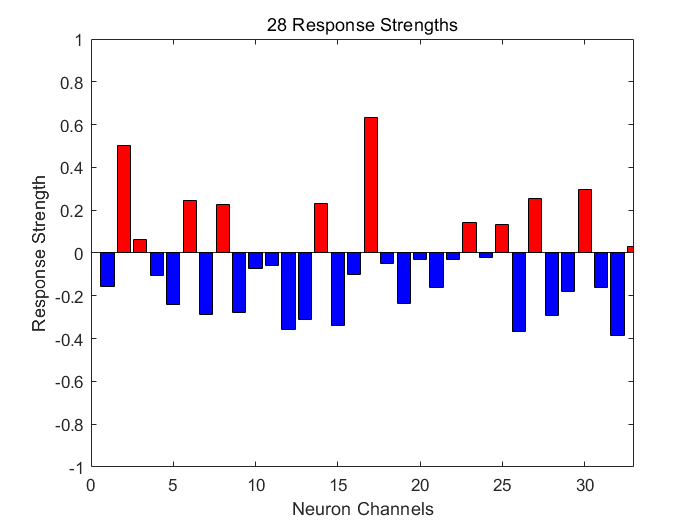


%% Response strengths of filtered data with bar graph

figure(11)
p = behavior_data_correlation_factors; p(p<=0) = 0; %only positive data
n = behavior_data_correlation_factors; n(n>0) = 0; % only negative data

bar(p, 'r'); hold on;  %positive data in red bar
bar(n, 'blue'); % negetive data in blue bar

title(name)
xlabel('Neuron Channels')
ylabel('Response Strength')
axis([0 (neuron_data_size(2)-1) -1 1])
hold off;

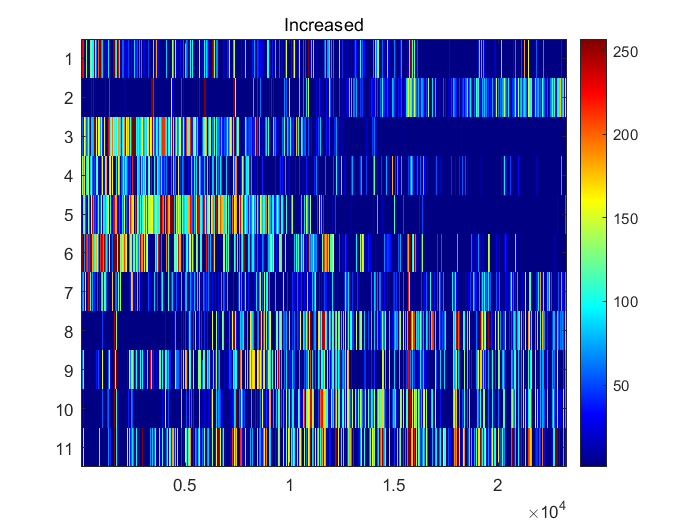

% Increased, Decreased, Neutral
label = zeros(1, neuron_data_size(2) - 1);
increased = double.empty;
decreased = double.empty;
neutral = double.empty;

for label_it = 1:neuron_data_size(2) - 1
    if behavior_data_correlation_factors(1, label_it) > sorted(round(shuffle_size * 0.95), label_it)
        label(1, label_it) = 1;
        increased = [increased neuron_data(:, label_it + 1)];
    elseif behavior_data_correlation_factors(1, label_it) < sorted(round(shuffle_size * 0.05), label_it)
        label(1, label_it) = -1;
        decreased = [decreased neuron_data(:, label_it + 1)];
    else
        neutral = [neutral neuron_data(:, label_it + 1)];
    end
end

image(increased');
colorbar;
colormap(jet(256));
title('Increased');

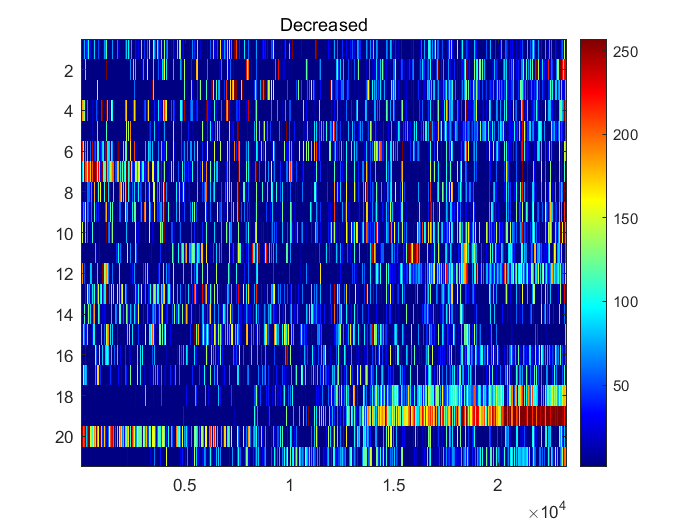


image(decreased');
colorbar;
colormap(jet(256));
title('Decreased');

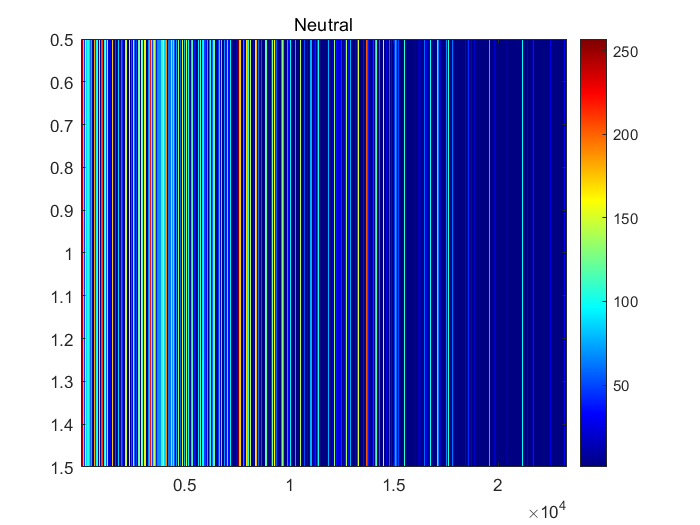


image(neutral');
colorbar;
colormap(jet(256));
title('Neutral');

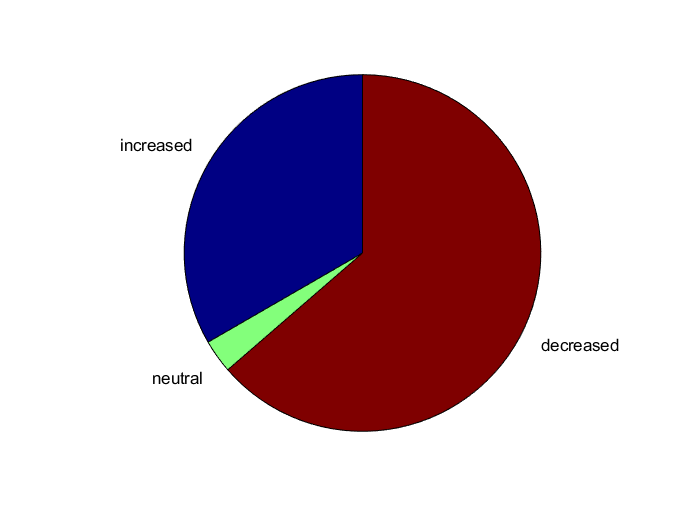

% Pie Chart
inc_size = size(increased);
dec_size = size(decreased);
neu_size = size(neutral);
X = [inc_size(2), neu_size(2), dec_size(2)];
labels = {'increased', 'neutral', 'decreased'};
pie(X, labels);

figure(987)
p = behavior_data_correlation_factors; p(p<=0) = 0; %only positive data
n = behavior_data_correlation_factors; n(n>0) = 0; % only negative data

bar(p, 'r'); hold on;  %positive data in red bar
bar(n, 'blue'); % negetive data in blue bar

title(behavior_name + " Response Strengths")
xlabel('Neuron Channels')
ylabel('Response Strength')
axis([0 (neuron_data_size(2)-1) -1 1])
hold off;

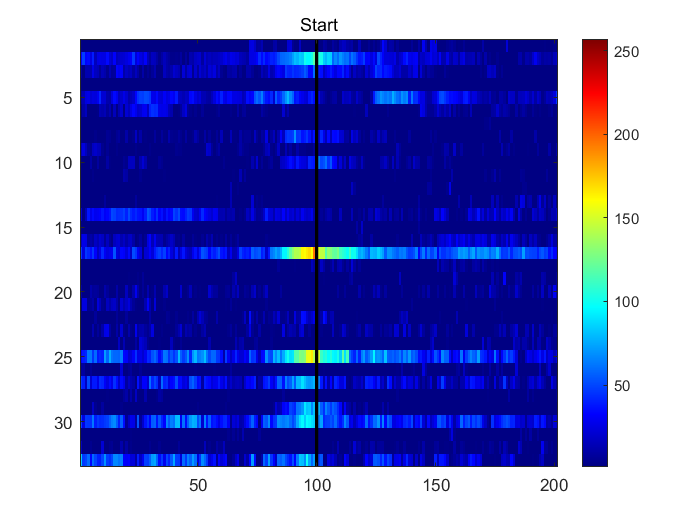

% heatmap

cell_activity = neuron_data(:, 2:neuron_data_size(2));
% cell_activity = filtered_data;
% cell_activity = increased;
% cell_activity = decreased;
interval = 100; % 5 sec
cell_activity_size = size(cell_activity);

Behavior_start_stop_size = size(Behavior_start_stop);
heatmap_data_start = zeros(interval*2+1, cell_activity_size(2));
heatmap_data_stop = zeros(interval*2+1, cell_activity_size(2));
for heatmap_it = 1:Behavior_start_stop_size(1)
    start = Behavior_start_stop(heatmap_it, 1);
    stop = Behavior_start_stop(heatmap_it, 2);
    heatmap_data_start = heatmap_data_start + cell_activity([start-interval:start+interval],:);
    heatmap_data_stop = heatmap_data_stop + cell_activity([stop-interval:stop+interval],:);
end
heatmap_data_start = heatmap_data_start / Behavior_start_stop_size(1);
heatmap_data_stop = heatmap_data_stop / Behavior_start_stop_size(1);
image(heatmap_data_start);
colorbar;
colormap(jet(256));
ylim = get(gca,'YLim');
line([interval, interval], [0, ylim(2)], 'Color', 'k', 'LineWidth', 2)
title('Start');

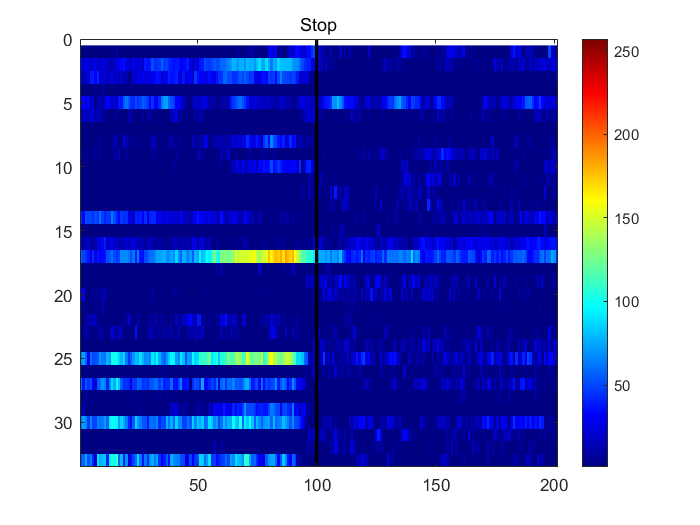


image(heatmap_data_stop');
colorbar;
colormap(jet(256));
title('Stop');
ylim = get(gca,'YLim');
line([interval, interval], [0, ylim(2)], 'Color', 'k', 'LineWidth', 2)

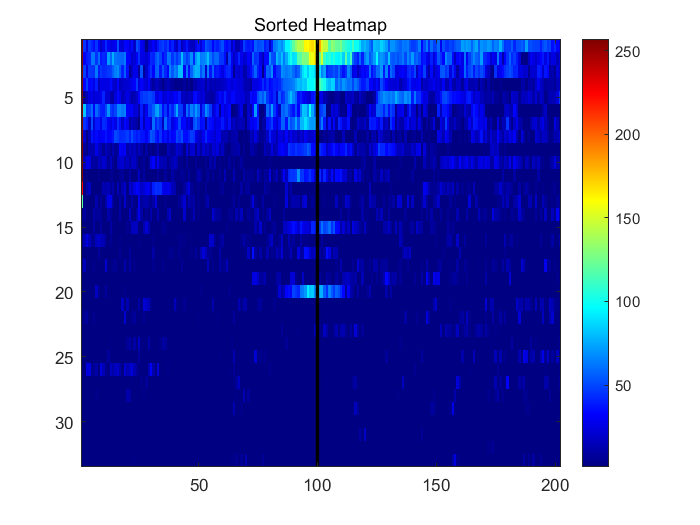

% heatmap sorting
sum_before = zeros(1, cell_activity_size(2));
sum_after = zeros(1, cell_activity_size(2));

for score_it = 1:interval
    sum_before = sum_before + heatmap_data_start(score_it, :);
    sum_after = sum_after + heatmap_data_start(score_it+interval, :);
end

scores = sum_before + sum_after; %heatmap_data_start(100, :);
score_map = [scores; heatmap_data_start];
sorted_heatmap = sortrows(score_map', 1, 'descend');
image(sorted_heatmap);
colorbar;
colormap(jet(256));
ylim = get(gca,'YLim');
line([interval, interval], [0, ylim(2)], 'Color', 'k', 'LineWidth', 2)
title('Sorted Heatmap');

% checking cell number of max increase/derease of each Behavior
[a,max_increase_cell_num]=find(behavior_data_correlation_factors_filtered==(max(behavior_data_correlation_factors_filtered)));
[e,max_decrease_cell_num]=find(behavior_data_correlation_factors_filtered==(min(behavior_data_correlation_factors_filtered)))

e = 1

max_decrease_cell_num = 32


% Getting the filtered data without adding the cell number
filtered_data_for_xcorr = zeros(neuron_data_size(1),neuron_data_size(2)-1);
for iterator5 = 2:(neuron_data_size(2))
filtered_data_for_xcorr(:,iterator5-1) = filtered_data(:, (iterator5-1)*2 - 1)/Normalizer;
end

% extracting the usefull data
% saved at extracted_data_xcorr
extracted_data_xcorr=[];
 for iterator6 = 1:Behavior_start_stop_size(1)
     tempmat=filtered_data_for_xcorr(Behavior_start_stop(iterator6,1):Behavior_start_stop(iterator6,2),:);
     extracted_data_xcorr = [extracted_data_xcorr;tempmat];
 end
 
 extracted_data_xcorr_size = size(extracted_data_xcorr)

extracted_data_xcorr_size =         2155          33


%  % Cross Correllation 
%  % Maximun increased cell as standard
%  for iterator7 = 1:neuron_data_size(2)-1
%  t=xcorr(extracted_data_xcorr(:,max_increase_cell_num),extracted_data_xcorr(:,iterator7))
%  end
 
% % sample cross correlation graph 
%  figure(1000)
%  crosscorr(extracted_data_xcorr(:,max_increase_cell_num),extracted_data_xcorr(:,6));
 
 % xcorr calculation
 % sample
[corr_value,lags] = xcorr(extracted_data_xcorr(:,max_increase_cell_num),extracted_data_xcorr(:,17),extracted_data_xcorr_size(1)-1,'coeff')

corr_value =     0.1126
   -0.0225
    0.0225
    0.0225
    0.0676
   -0.0450
   -0.0225
    0.0450
    0.0225
   -0.0225


lags =        -2154       -2153       -2152       -2151       -2150       -2149       -2148       -2147       -2146       -2145       -2144       -2143       -2142       -2141       -2140       -2139       -2138       -2137       -2136       -2135       -2134       -2133       -2132       -2131       -2130       -2129       -2128       -2127       -2126       -2125       -2124       -2123       -2122       -2121       -2120       -2119       -2118       -2117       -2116       -2115       -2114       -2113       -2112       -2111       -2110       -2109       -2108       -2107       -2106       -2105


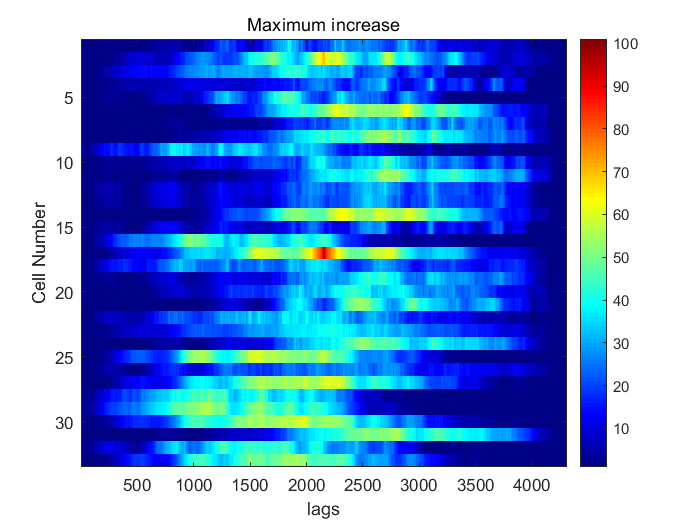

% Maximum increased cell as a standard
% checking the entire lags

% Making an empty matrix
xcorr_data_Maximum_increase = zeros(neuron_data_size(2)-1,2*extracted_data_xcorr_size(1)-1);

% Applying the data in the matrix above
for iterator7 = 1 : neuron_data_size(2)-1
    [corr_value,lags] = xcorr(extracted_data_xcorr(:,max_increase_cell_num),extracted_data_xcorr(:,iterator7),extracted_data_xcorr_size(1)-1,'coeff');
    xcorr_data_Maximum_increase(iterator7,:) = corr_value;
end

figure(9000)
h=image(xcorr_data_Maximum_increase.*100);
colorbar;
colormap(jet(100));
title('Maximum increase');

xlabel('lags')
ylabel('Cell Number')


% checking the cells that have higher corr_values than the threshold


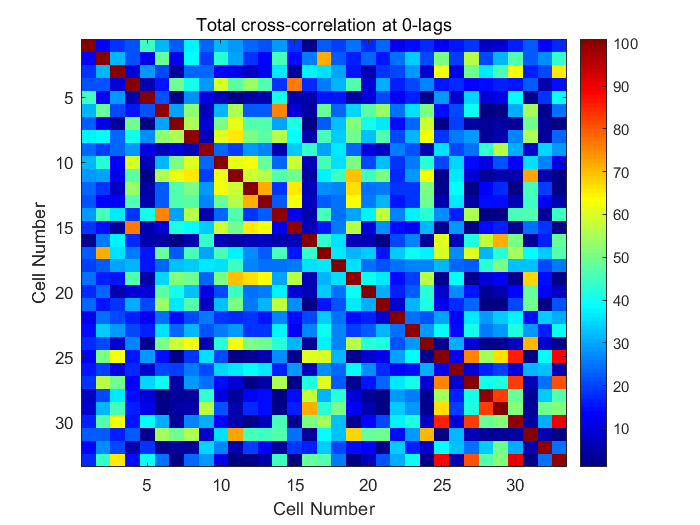

% cell_num x cell_num matrix
% checking the lags on 0

% making an empty matrix
xcorr_data_total_at_zero_lags = zeros(neuron_data_size(2)-1);

% applying the data
for iterator8 = 1 : neuron_data_size(2)-1
    for iterator9 = 1 : neuron_data_size(2)-1
        [corr_value,lags] = xcorr(extracted_data_xcorr(:,iterator8),extracted_data_xcorr(:,iterator9),extracted_data_xcorr_size(1)-1,'coeff');
        xcorr_data_total_at_zero_lags(iterator8,iterator9) = corr_value(extracted_data_xcorr_size(1),1);
    end
end

figure(9001)
image(xcorr_data_total_at_zero_lags.*100);
colorbar;
colormap(jet(100));
title('Total cross-correlation at 0-lags');
xlabel('Cell Number')
ylabel('Cell Number')


% checking the cells that have higher corr_values than the threshold
Threshold_total_at_zero_lags = input('input Threshold between 0 ~ 100(%) : ')

Threshold_total_at_zero_lags = 80

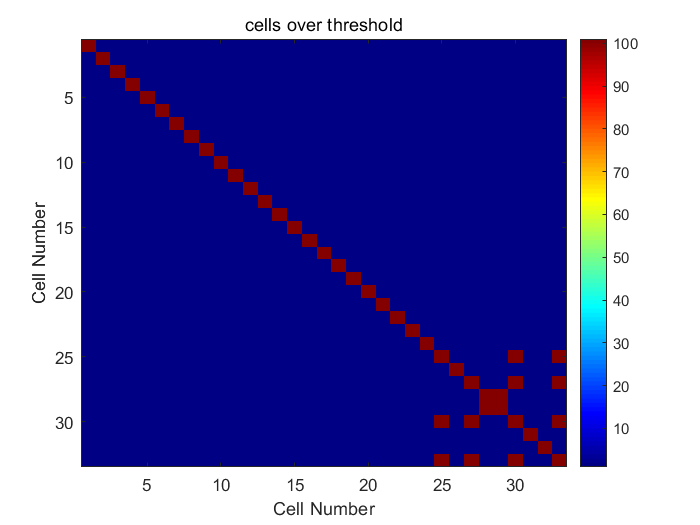


cells_over_threshold_total_at_zero_lags = zeros(neuron_data_size(2)-1);
cell_count = 0;

for iterator10 = 1 : neuron_data_size(2)-1
    for iterator11 = 1 : neuron_data_size(2)-1
        if xcorr_data_total_at_zero_lags(iterator10,iterator11)*100 >= Threshold_total_at_zero_lags
            cells_over_threshold_total_at_zero_lags(iterator10,iterator11) = 100;
            cell_count = cell_count +1;
        end
    end
end

figure(9002)
image(cells_over_threshold_total_at_zero_lags);
colorbar;
colormap(jet(100));
title('cells over threshold');
xlabel('Cell Number')
ylabel('Cell Number')

% cell_num x cell_num matrix
% picking the lags with the largest corr value
% heatmap on the bottom 
% 3-D graph on lags over the heatmap
